## Corr_len_cal

Find correlation length scale from measurement 

- use 1-D transects

- use 2-D plane

- compare length scales of both cases

Assumption 

- Stationary

- Intrinsic

-  Isotropic

clear
close all

ACO_lat= 22.738772;                  % June 2017
ACO_lon= -158.006186;                % June 2017

Load an inversion file: October 2018 (HEM)

cd /Users/testuser/Documents/ONR_RAP/Data/inversion_file
load('HEM_inverse_solution_Oct2018_originaldepth.mat')
tx_lat_HEM = tx_lat;
tx_lon_HEM = tx_lon;

Extract ttp measurements contributed from ocean features and plot tx map

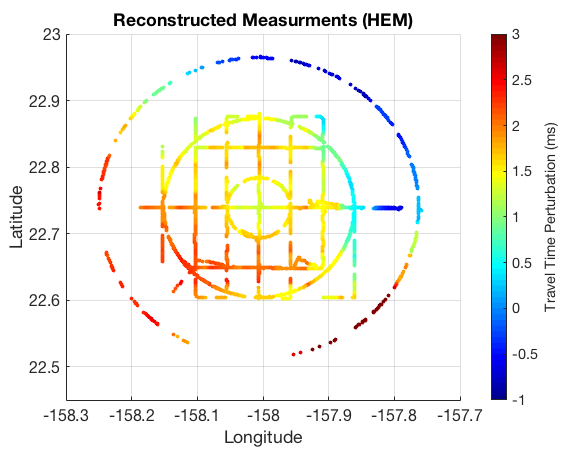

d_recov_ocean_HEM = G(:,1:end-3)*m_recov(1:end-3);

f1 = figure(1);
s1 = scatter(tx_lon_HEM,tx_lat_HEM);
color_range = [-1 3];
fpos = [0 0.2];
plot_RAP_txmap(f1,s1,'Reconstructed Measurments (HEM)',color_range,d_recov_ocean_HEM,fpos);

Load an inversion file: October 2018 (icListen)

cd /Users/testuser/Documents/ONR_RAP/Data/inversion_file
load('icListen_inverse_solution_Oct2018_originaldepth.mat')
tx_lat_ic = tx_lat;
tx_lon_ic = tx_lon;

Extract ttp measurements contributed from ocean features and plot tx map

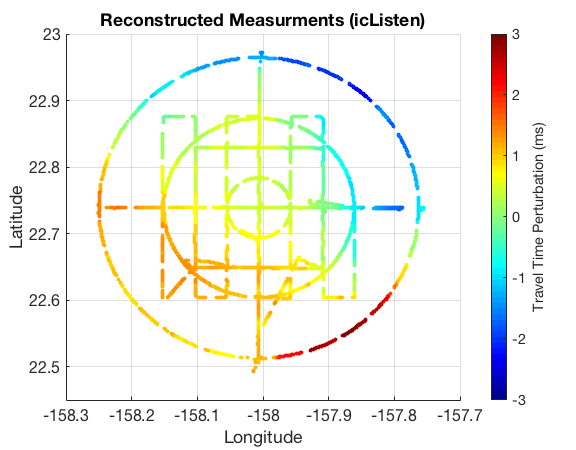

d_recov_ocean_ic = G(:,1:end-3)*m_recov(1:end-3);

f2 = figure(2);
s2 = scatter(tx_lon_ic,tx_lat_ic);
color_range = [-3 3];
fpos = [0.5 0.2];
plot_RAP_txmap(f2,s2,'Reconstructed Measurments (icListen)',color_range,d_recov_ocean_ic,fpos);

**Set up radial transect** (zonal transect)

Lat = 22.73-22.75

Lon = -157.8 – -158.30

resample data

HEM

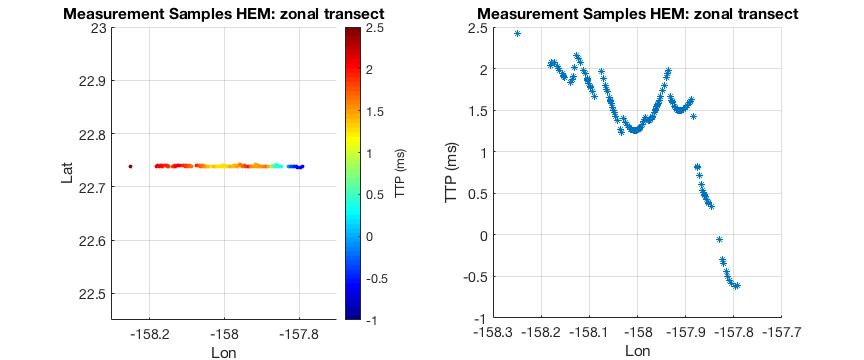

lonlim = find((tx_lon_HEM<-157.75 & tx_lon_HEM >-158.3)  == 1);
latlim = find((tx_lat_HEM< 22.742 & tx_lat_HEM > 22.737) == 1);
keep_ind = intersect(lonlim,latlim);
% resample
L = 5;
keep_ind = keep_ind(1:L:end);

d_HEM1 = d_recov_ocean_HEM(keep_ind);
tx_lon_HEM1 = tx_lon_HEM(keep_ind);
tx_lat_HEM1 = tx_lat_HEM(keep_ind);

% sort array elements from left to right
[tx_lon_HEM1,new_ind] = sort(tx_lon_HEM1);
tx_lat_HEM1 = tx_lat_HEM1(new_ind);
d_HEM1 = d_HEM1(new_ind);
% travel time perturbation in ms
ttp = d_HEM1*1000;

f3 = figure(3);
clf
subplot(1,2,1)
s3 = scatter(tx_lon_HEM1,tx_lat_HEM1);
color_range = [-1 2.5];
fpos = [0.1 0.6];
color_data = ttp;
set(f3,'Units','normalized','Position',[fpos 0.6 0.4])
set(s3,'Marker','o','MarkerFaceColor','flat','SizeData',10,'CData',color_data)
xlim([-158.3 -157.7])
ylim([22.45 23])
grid on
xlabel('Lon')
ylabel('Lat')

cbar = colorbar;
caxis([color_range]);
colormap jet;
cbar.Label.String = 'TTP (ms)';
set(gca,'fontsize',14)
title('Measurement Samples HEM: zonal transect','fontsize',16)

subplot(1,2,2)
scatter(tx_lon_HEM1,ttp,[],'*');
grid on
ylabel('TTP (ms)')
xlabel('Lon')
ylim([-1 2.5])
set(gca,'fontsize',14)
title('Measurement Samples HEM: zonal transect','fontsize',16)

**Create experimental (semi)variogram** 

$\gamma(h) = \frac{1}{2N_k} \sum\limits_{i=1}^{N_k}(z(\mathbf{x}_i)-z(\mathbf{x'}_i))^2$ where


$$z \text{ = data }$$


 
$$N_k =\text{number of pairs}$$



$$\mathbf{x}_i = \text{position coordinates}$$


Pairing 2 data points 

- In the outer loop, fix the first point, starting from the western end to the eastern end.

- In the inner loop, loop over data points located to the east of the first point. Calculate gamma, and separation distance in meters.

- Create separation bins

- Group gamma values by separation bins and average them out

sample = length(ttp);    
all_Nk = sample*(sample-1)/2;   % gamma data points 
gamma = zeros(1,all_Nk);         % raw gamma
separation = zeros(1,all_Nk);    % separation 
cdata = zeros(1,all_Nk);    % color vector
counter =1;
% loop over pairs of measurements
for ii = 1:sample
    % 1st data point
   for jj = ii:sample   % from iith data point to the last data point
       % 2nd data point
       % calcualte 1. separation 2. raw variogram
       [separation(counter),~] = distance(tx_lat_HEM1(ii),tx_lon_HEM1(ii),tx_lat_HEM1(jj),tx_lon_HEM1(jj),referenceEllipsoid('WGS84'));
       gamma(counter) = 0.5*(ttp(ii) - ttp(jj))^2;
       cdata(counter) = ii;
       counter = counter +1;
   end
end


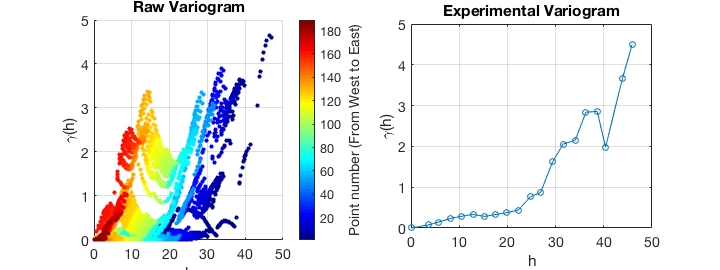

% raw variogram
f4 = figure(4);
clf
set(f4,'Units','normalized','Position',[0.5 0.5 0.5 0.3])
subplot(1,2,1)
svar = scatter(separation/1000,gamma,20,cdata,'filled');
cbar = colorbar;
cbar.Label.String = 'Point number (From West to East)';
cbar.Label.FontSize = 14;
colormap jet
grid on
xlabel('h')
ylabel('\gamma(h)')
xlim([0 50])
xticks(0:10:50)
title('Raw Variogram')
set(gca,'fontsize',14)


% experimental variogram
bin_num = 20;
sep_int = max(separation)/bin_num;
ex_gamma = zeros(1,bin_num+1);      % experimental variogram
hk = zeros(1,bin_num+1);            % separation bin
for ii = 2:bin_num+1
    % loop over all bins
    % create indicies of elements oin the current group
    ind = find((separation <= sep_int*ii) & (separation > sep_int*(ii-1))); % indices of elements in the current interval
    % number of elements in this group
    Nk = length(ind);
    
    ex_gamma(ii) = sum(gamma(ind))/Nk;
    hk(ii) = 1/Nk*sum(separation(ind));
end

figure(4)
subplot(1,2,2)
p1 =  plot(hk/1000,ex_gamma,'Linewidth',1,'Marker','o');
grid on
xlabel('h')
ylabel('\gamma(h)')
title('Experimental Variogram')
set(gca,'fontsize',14)